# Using singular control regularization and exterior penalty on Goddard's problem

## 1) Original problem

Goddard's problem consits in maximizing the height of a rocket whose dynamics is describe by three variables: its altitude $h$, its vertical velocity $v$ and its mass $m$.

The control is $w$, the optimal control problem with free final time $T$:

$J=\min -h\left(T\right)=\int_0^T -v\cdot \textrm{dt}$      (1)

$\frac{\textrm{dh}}{\textrm{dt}}=v$                                        (2)

$\frac{\textrm{dv}}{\textrm{dt}}=\frac{w-D}{m}-\frac{1}{h^2 }$                         (3)

$\frac{\textrm{dm}}{\textrm{dt}}=-\frac{w}{c}$                                   (4)

$w\in \left\lbrack \underline{w} ,\bar{w} \right\rbrack$                                  (5)

$q\left(h,v\right)\le \bar{q}$                                  (6)

Boundary conditions: $h\left(0\right)=1$, $m\left(0\right)=1$, $m\left(T\right)=0\ldotp 6$, $v\left(0\right)=0$, $T=\textrm{free}$              (7)

The aeorodynamic drag is $D=\textrm{Cte}\cdot q\left(h,v\right)$ whith the dynamic pressure $q\left(h,v\right)=0\ldotp 5\rho_0 v^2 \exp \left(\beta \left(1-h\right)\right)$.

This problem is therefore state constrained due to constraint (6). The problem is also affine in the control $w$ . 

## 2) Problem rewriting

To deal with the free final time $T$, let us introduce the following normalized time variable $\alpha \in \left\lbrack 0,1\right\rbrack$ such that $t=\alpha T$ along with the following dynamics :

$\frac{\textrm{dT}}{d\alpha }=0$                                         (8)

In the rest of the document, all the time derivatives are with respect to the normalized time variable $\alpha$.

The state vector is $x={\left(h,v,m,T\right)}^T$

To ease the management of the singular control, we introduce a normalized control $u\in \left\lbrack -1,1\right\rbrack$:

$w=d_0 +d_1 u$                               (9)

$d_0 =\frac{\bar{w} +\underline{w} }{2}$, $d_1 =\frac{\bar{w} -\underline{w} }{2}$.

As a result, the optimal control problem (1)-(7) is rewriten as:

$J=\min \int_0^T l\left(x\right)\textrm{dt}$                       (10)

$\frac{\textrm{dx}}{d\alpha }=f_0 \left(x\right)+f_1 \left(x\right)u$                     (11)

$-1\le u\le 1$                                (12)

$q\left(h,v\right)\le \bar{q}$                                 (13)

$h\left(0\right)=1$, $m\left(0\right)=1$, $m\left(1\right)=0\ldotp 6$, $v\left(0\right)=0$, $T=\textrm{free}$     (14)

with $f_0 \left(x\right)=\left(\begin{array}{c}
v\\
\frac{1}{m}\left(d_0 -D\left(x\right)\right)-\frac{1}{h^2 }\\
-\frac{d_0 }{c}\\
0
\end{array}\right)T$ and $f_1 \left(x\right)=\left(\begin{array}{c}
0\\
\frac{d_1 }{m}\\
-\frac{d_1 }{c}\\
0
\end{array}\right)T$.

## 3) Derivation of optimality condition

To deal with the state constraint, we introduce an external penalty to the cost (10) through a small parameter $\varepsilon_p$.

$J^{\prime } =\min \int_0^T \left\lbrack l\left(x\right)+P\left(q\left(h,v\right)-\bar{q} \right)\right\rbrack \textrm{dt}$                       (10)

with $P\left(z\right)=\frac{1}{\varepsilon_p }\Gamma \left(z\right)z^n$

The original problem (1)-(7) is recovered when $\varepsilon_p \longrightarrow 0^+$.

To deal with the singular control, the approach suggested by C.R. Heidrich in [1] is implemented. A new regularized, unconstrained, control $u_r \in R$ is introduced along with a small parameter $\varepsilon_r >0$:

$u\left(u_r \right)=\frac{2}{\pi }\tan^{-1} \left(\frac{u_r }{\varepsilon_r }\right)$                                                     (11)

The regularization is achieved by an additionnal term introduced in the running cost (10):

$J^{\prime \prime } =\min \int_0^T \left\lbrack l\left(x\right)+P\left(q\left(h,v\right)-\bar{q} \right)+l_r \left(x\right)\right\rbrack \textrm{dt}$           (12)

with $l_r \left(x\right)=\frac{\varepsilon_r }{\pi }\ln \left(1+\frac{\varepsilon_r^2 }{\pi^2 }\right)$.

The problem to be solved is (12), (11), (14) and the original problem is recovered when $\varepsilon_p \longrightarrow 0^+$ and $\varepsilon_r \longrightarrow 0^+$.

With $p=\left(p_i \right)$ the costate, the Hamiltonian is :

$H\left(x,u_r ,p\right)=l\left(x\right)+P\left(q\left(h,v\right)-\bar{q} \right)+l_r \left(x\right)+p^T \left(f_0 \left(x\right)+f_1 \left(x\right)u\left(u_r \right)\right)$    (13)

$H\left(x,u_r ,p\right)=H_0 \left(x\right)+P\left(q\left(h,v\right)-\bar{q} \right)+H_1 \left(x\right)u\left(u_r \right)$                            (14)

The optimal control is [1]:

$u_r =-H_1 \left(x\right)$                        (15)

Let $z\left(\alpha \right)=\left(\begin{array}{c}
x\left(\alpha \right)\\
p\left(\alpha \right)
\end{array}\right)$. The optimal control problem  (12), (11), (14) is reduced to the following BVP:

$\frac{\textrm{dz}}{d\alpha }=F\left(\alpha ,z,\right)$                                  (16)

$G\left(z\left(0\right),z\left(1\right)\right)=0$                            (17)

 $F\left(\alpha ,z,\right)=\left(\begin{array}{c}
f_0 \left(x\right)+f_1 \left(x\right)u\left(u_r \right)\\
-\frac{\partial H}{\partial x}
\end{array}\right)$       (18)


$$G\left(z\left(0\right),z\left(1\right)\right)=\left(\begin{array}{c}
h\left(0\right)-1\\
p_1 \left(1\right)\\
v\left(0\right)\\
p_2 \left(1\right)\\
m\left(0\right)-1\\
p_3 \left(1\right)\\
p_4 \left(0\right)\\
p_4 \left(1\right)
\end{array}\right)$$


## 4) Matlab code

The optimal control problem (1)-(7) is first rewriten using a no

clearvars;close all; clc

### 4.1) Problem parameters

Let us define the problem parameters.

% Model parameters
cte=1/20;c=0.5;beta0=500;ThrustMin=0;ThrustMax=3.5;qmax=10;rho0=620/cte;
constraintAccuracy=1e-4;

% Control scaling
d0=(ThrustMax+ThrustMin)/2;d1=(ThrustMax-ThrustMin)/2;

% Initial & final conditions
m0=1;mT=0.6;h0=1;

% Penalty parameter
eps_pen=1e8;

We now define the `fixedParams` structure that contains all the data remain constant during the continuation procedure.

fixedParams=createStructureFromVariable(cte,c,beta0,qmax,rho0,d0,d1,eps_pen,mT,h0,m0,constraintAccuracy);


### 4.1) First continuation procedure

The first continuation procedure aims to bring the regularization parameter $\varepsilon_r$ toward a very small value. 

A constant initial solution is considered. 

Tguess=2;
yInit=[h0;0;m0;Tguess;0;0;0;0];

nInit=500;
solInit.x=linspace(0,1,nInit);
solInit.y=repmat(yInit,[1 nInit]);


Now we can implementat of the first initial continuation procedure.


tic
fprintf('======================================\n')

fprintf('1) Regularize singular control\n')

1) Regularize singular control


fprintf('======================================\n')

We start by defining the continuation procedure parameters.

% Continuation parameters initial & final values
paramStart.eps_singular=1e2;
paramEnd.eps_singular=1e-6;

A logarithmic scheduler is considered. We use default parameters values except for the final value of the scheduling parmeter which is set to $\lambda_{\min } ={10}^{-12}$.

% Define scheduler
scheduler=logScheduler(paramStart,paramEnd, fixedParams=fixedParams,lambdaMin=1e-12);


We defined the problem to be solved as a `bvp4or5c` object. We used loose solver tolerances for the initial continuation procedure, which will be refined in the next one.

% Set coarse tolerance to reduce computation time
bvpOpt=bvpset('RelTol',1e-2,'AbsTol',1e-4,"Nmax",60000);
problem=bvp4or5c('bvp5c',@generateFodeFcn,@generateBCFcn,bvpOptions=bvpOpt);

The continuation procedure can be executed. We use additional functions passed as parameters and given in this section.

- modifySolutionFcn : This function allows adding fields of interest such as Thrust $w$, dynamic pressre $q$, control $u$ to the solution.

- plotFigFcn : This function plots intermediate solutions to monitor the progress of the continuation procedure.

- preIterPrintFcn : This function displays values of the continuation parameters.

% Define & run continuation procedure
fprintf('Continuation procedure on eps_singular\n')

Continuation procedure on eps_singular


Checking initial solution feasability
Done (initial solution is feasible)
Iter : 002 Lambda : 7.6190e-01 delta : 7.62e-01 eps_singular : 7.619e+01 
Iter : 003 Lambda : 5.5286e-01 delta : 7.26e-01 eps_singular : 5.529e+01 
Iter : 004 Lambda : 3.8206e-01 delta : 6.91e-01 eps_singular : 3.821e+01 
Iter : 005 Lambda : 2.5146e-01 delta : 6.58e-01 eps_singular : 2.515e+01 
Iter : 006 Lambda : 1.5762e-01 delta : 6.27e-01 eps_singular : 1.576e+01 
Iter : 007 Lambda : 9.4095e-02 delta : 5.97e-01 eps_singular : 9.409e+00 
Iter : 008 Lambda : 5.3497e-02 delta : 5.69e-01 eps_singular : 5.350e+00 
Iter : 009 Lambda : 2.8967e-02 delta : 5.41e-01 eps_singular : 2.897e+00 
Iter : 010 Lambda : 1.4938e-02 delta : 5.16e-01 eps_singular : 1.494e+00 
Iter : 011 Lambda : 7.3365e-03 delta : 4.91e-01 eps_singular : 7.337e-01 
Iter : 012 Lambda : 3.4316e-03 delta : 4.68e-01 eps_singular : 3.432e-01 
Iter : 013 Lambda : 1.5287e-03 delta : 4.45e-01 eps_singular : 1.529e-01 
Iter : 014 Lambda : 6.4855e-04 delta :

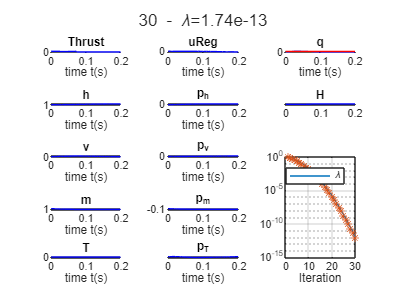

cont1=continuationProcedure(problem,scheduler,solInit, ...
    "modifySolutionFcn",@modifySolutionFcn,...
    "storeSolutionInHistory",true,...
    "plotFigFcn",@plotFigFcn,...
    "preIterPrintFcn",@preIterPrintFcn);
cont1.run;

duration1=toc;
solInit2=cont1.sol;
fprintf('Problem sucessfully solved\n');

Problem sucessfully solved


### 4.2) Second continuation procedure

The second continuation procedure aims to bring the penalization parameter $\varepsilon_p$ toward a very small value.

fprintf('====================================================\n');

fprintf('2) Introduce state constraint using an exterior penalty\n');

2) Introduce state constraint using an exterior penalty


fprintf('====================================================\n');

eps_singular=paramEnd.eps_singular; % Save last value
clear paramStart paramEnd fixedParams

We now define the continuation procedure parameters.

% Create a structure with fixed params
fixedParams=createStructureFromVariable(cte,c,beta0,qmax,rho0,d0,d1,eps_singular,mT,h0,m0,constraintAccuracy);

% Set continuation procedure initial & final values
paramStart.eps_pen=eps_pen;    paramEnd.eps_pen=1e-5;
paramStart.RelTol=1e-2;        paramEnd.RelTol=1e-6;
paramStart.AbsTol=1e-4;        paramEnd.AbsTol=1e-9;

Initial solution is supposed feasible
Iter : 002 Lambda : 8.8235e-01 delta : 8.82e-01 eps_pen : 8.824e+07 RelTol : 8.824e-03 AbsTol : 8.824e-05 
Iter : 003 Lambda : 7.6328e-01 delta : 8.65e-01 eps_pen : 7.633e+07 RelTol : 7.633e-03 AbsTol : 7.633e-05 
Iter : 004 Lambda : 6.4733e-01 delta : 8.48e-01 eps_pen : 6.473e+07 RelTol : 6.474e-03 AbsTol : 6.473e-05 
Iter : 005 Lambda : 5.3823e-01 delta : 8.31e-01 eps_pen : 5.382e+07 RelTol : 5.383e-03 AbsTol : 5.382e-05 
Iter : 006 Lambda : 4.3874e-01 delta : 8.15e-01 eps_pen : 4.387e+07 RelTol : 4.388e-03 AbsTol : 4.387e-05 
Iter : 007 Lambda : 3.5063e-01 delta : 7.99e-01 eps_pen : 3.506e+07 RelTol : 3.507e-03 AbsTol : 3.506e-05 
Iter : 008 Lambda : 2.7472e-01 delta : 7.84e-01 eps_pen : 2.747e+07 RelTol : 2.748e-03 AbsTol : 2.747e-05 
Iter : 009 Lambda : 2.1102e-01 delta : 7.68e-01 eps_pen : 2.110e+07 RelTol : 2.111e-03 AbsTol : 2.110e-05 
Iter : 010 Lambda : 1.5892e-01 delta : 7.53e-01 eps_pen : 1.589e+07 RelTol : 1.590e-03 AbsTol : 1.589e-05 

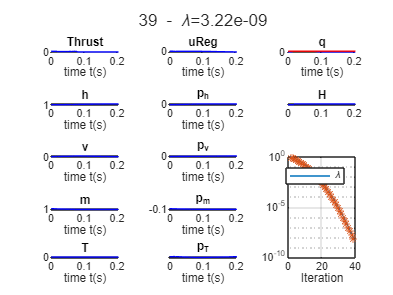

% Define a logarithmic scheduler
scheduler=logScheduler(paramStart,paramEnd, fixedParams=fixedParams,initialDelta=0.9,beta=1.02);
problem=bvp4or5c('bvp5c',@generateFodeFcn,@generateBCFcn,fcnForBvpOptions=@GenerateBvpOptions);

% Define and run continuation procedure
cont2=continuationProcedure(problem,scheduler,solInit2, ...
    "modifySolutionFcn",@modifySolutionFcn,...
    "storeSolutionInHistory",true,...
    "doNotCheckInitialSol",true,...
    "plotFigFcn",@plotFigFcn,...
    "preIterPrintFcn",@preIterPrintFcn);%,...
% "userStopFcn",@userStopFcn);
cont2.run;

duration2=toc;
% Save data
sol=cont2.sol;
fprintf('Problem sucessfully solved\n')

Problem sucessfully solved


save goddard_pb_Data

### 4.3) Problem functions

Dynamic pressure

% =========================================================================
% Problem functions
% =========================================================================
function res=qFun(x,rho0,beta0)
% Dynamic pressure
h=x(1);v=x(2);
res=0.5*rho0*v^2*exp(beta0*(1-h));
end

Hamiltonian and optimal control computation.

function [uReg,H,u,Thrust]=computeControlHamiltonian(x,p,q,c,cte,d0,d1,qmax,eps_singular,eps_pen, penaltyActivated)
p1=p(1);p2=p(2);p3=p(3);
h=x(1);v=x(2);m=x(3);T=x(4);

% Regularized control from Heidrich's GRCM
uReg=(T.*d1.*p3)./c - (T.*d1.*p2)./m; % uReg in [-inf,inf]
u=(2*atan(uReg/eps_singular))/pi;     % u in [-1,1];
Thrust=d0+d1*u;                       % Thrust in [ThrustMin,ThrustMax];

H=(eps_singular*log(uReg^2/eps_singular^2 + 1))/pi - T*v + T*p1*v + T*p2*((Thrust - cte*q)/m - 1/h^2) ...
    - (T*Thrust*p3)/c + (T*penaltyActivated*(q - qmax)^2)/eps_pen;
end

BVP dyanmics.


function dydt=fdyn(~,y,beta0,c,cte,d0,d1,rho0,qmax,eps_pen,eps_singular)
% BVP dynamics
x=y(1:4);p=y(5:end);
h=x(1);v=x(2);m=x(3);T=x(4);
p1=p(1);p2=p(2);p3=p(3);

q=qFun(x,rho0,beta0);
penaltyActivated=q>qmax;

[~,~,~,Thrust]=computeControlHamiltonian(x,p,q,c,cte,d0,d1,qmax,eps_singular,eps_pen, penaltyActivated);

% Compute system dynamics
D=q*cte;
dxdt=[v;
    (Thrust-D)/m-1/h^2;
    -Thrust/c;0]*T;

% Optimal costate dynamics
term1=rho0*v*exp(-beta0*(h - 1));
dpdt=[
    (2*T*beta0*penaltyActivated*q*(q - qmax))/eps_pen - T*p2*(2/h^3 + (beta0*cte*q)/m);
    T - T*p1 + (T*cte*p2*term1)/m - (2*T*penaltyActivated*term1*(q - qmax))/eps_pen;
    (T*p2*(Thrust - cte*q))/m^2;
    v - p1*v - p2*((Thrust - cte*q)/m - 1/h^2) - (penaltyActivated*(q - qmax)^2)/eps_pen + (Thrust*p3)/c;
    ];
% BVP dynamics
dydt=[dxdt;dpdt];
end

BVP boundary condition

function res=bcfun(ya,yb,h0,m0,mT)
ha=ya(1);va=ya(2);ma=ya(3);p_Ta=ya(8);

mb=yb(3);p_hb=yb(5);p_vb=yb(6);p_Tb=yb(8);


% Boundary condition to be canceled
res=[ha-h0;  % h(0)=h0
    p_hb;    %  p_h(1)=0

    va;      % v(0)=0
    p_vb;    %  p_v(1)=0

    ma-m0;   % m(0)=m0
    mb-mT;   %m(1)=mT

    p_Ta;    %  p_T(0)=0
    p_Tb;    %  p_T(1)=0
    ];
end


#### 4.4) Continuation procedure functions

function fode=generateFodeFcn(continuationParams,fixedParams)
% retrieve a handle to the ode function with the current parameters
% values
retrieveContinuationParameters({continuationParams,fixedParams});
fode=@(t,y) fdyn(t,y,beta0,c,cte,d0,d1,rho0,qmax,eps_pen,eps_singular);
end

function bcond=generateBCFcn(continuationParams,fixedParams)
% retrieve a handle to the boundary condition function with the
% current parameters values
retrieveContinuationParameters({continuationParams,fixedParams});
bcond=@(ya,yb) bcfun(ya,yb,h0,m0,mT);
end


### 4.5) Helper functions

This function allows adding fields of interest such as Thrust $w$, dynamic pressre $q$, control $u$ to the solution.

function sol=modifySolutionFcn(sol,iterSuccess,continuationParams,fixedParams)
if iterSuccess
    retrieveContinuationParameters({continuationParams,fixedParams});

    nx=length(sol.x);
    sol.u=zeros(1,nx);
    sol.uReg=zeros(1,nx);
    sol.H=zeros(1,nx);
    sol.q=zeros(1,nx);

    for i=1:length(sol.x)
        x=sol.y(1:4,i);p=sol.y(5:end,i);

        q=qFun(x,rho0,beta0);
        sol.q(i)=q;
        constraint=sol.q(i)-qmax;
        penaltyActivated=constraint>0;

        [uReg,H,u,Thrust]=computeControlHamiltonian(x,p,q,c,cte,d0,d1,qmax,eps_singular,eps_pen, penaltyActivated);

        sol.uReg(i)=uReg;
        sol.H(i)=H;
        sol.u(i)=u;
        sol.Thrust(i)=Thrust;
    end

end
end


This function plots intermediate solutions to monitor the progress of the continuation procedure. 

function dataPlot=plotFigFcn(dataPlot,status,id,sol,continuationParams,fixedParams,str)
% Display solution using the provide iterativeDisplay "id"
retrieveContinuationParameters({continuationParams,fixedParams});

% Initialization : prepare the figure layout
h=id.figure;
% id.setOnce(h,'visible','on'); % Undock figure

T=sol.y(4,1);
sol.x=sol.x*T;

ny=size(sol.y,1);
hTile=id.tiledlayout(ny/2+1,3);
% Add a title with lambda value & iteration
id.setOnce(hTile.Title,'String',str);

id.nexttile;
id.plot(sol.x,sol.Thrust,'b');
id.title('Thrust');
id.grid('on');
id.xlabel('time t(s)');

id.nexttile;
id.plot(sol.x,sol.uReg,'b');
id.title('uReg');
id.grid('on');
id.xlabel('time t(s)');

id.nexttile;
id.plot(sol.x,sol.q,'b');
id.hold('on')
id.plot(sol.x([1 end]),[qmax qmax],'r');
id.title('q');
id.grid('on');
id.xlabel('time t(s)');

lgd={'h','v','m','T'};
for i=1:ny/2
    id.nexttile;
    id.plot(sol.x,sol.y(i,:),'b');
    id.title(sprintf('%s',lgd{i}));
    id.grid('on');
    id.xlabel('time t(s)');


    id.nexttile;
    id.plot(sol.x,sol.y(ny/2+i,:),'b');
    id.title(sprintf('p_%s',lgd{i}));
    id.grid('on');
    id.xlabel('time t(s)');

    if i==1
        id.nexttile;
        id.plot(sol.x,sol.H,'b');
        id.title('H');
        id.grid('on');
    elseif i==2
        id.nexttile([ny/2-1 1]);
        plotHistory(dataPlot,id,"log");
        id.grid('on');
    end
end

% Force figure update
drawnow;
end

 This function displays values of the continuation parameters.

function preIterPrintFcn(algorithmState, continuationParams, fixedParams)
fields=fieldnames(continuationParams);
fprintf('%s ',algorithmState.schedulerStateStr);
for i=1:length(fields)
    fprintf('%s : %.3e ',fields{i},continuationParams.(fields{i}));
end
fprintf('\n');
end

This function allows adapting the solver tolerence within a continuation procedure.

function bvpOptions=GenerateBvpOptions(continuationParams,fixedParams)
% Retrieve parameters relTol and absTol from the continuation parameters (or
% fixedParam)
retrieveContinuationParameters({continuationParams,fixedParams});

% Build the bvpOptions dynamically
bvpOptions=bvpset("AbsTol",AbsTol,"RelTol",RelTol,"Nmax",80000);
end

## References

[1] C. R. Heidrich, M. J. Sparapany, et M. J. Grant, « Generalized Regularization of Constrained Optimal Control Problems », *Journal of Spacecraft and Rockets*, vol. 59, no 4, p. 1096‑1110, juill. 2022, doi: 10.2514/1.A35229.